# Toy Experiment for non-parametric compare

## DGP

Adapted from Hastie & Tibshirani, p 12

rng default; % For testing

n = 100;
k = 1;

X = normrnd(0,1,n,k);
X = sort(X)

X =    -2.9443
   -2.2588
   -1.9330
   -1.7947
   -1.7115
   -1.4916
   -1.4224
   -1.4023
   -1.3499
   -1.3077


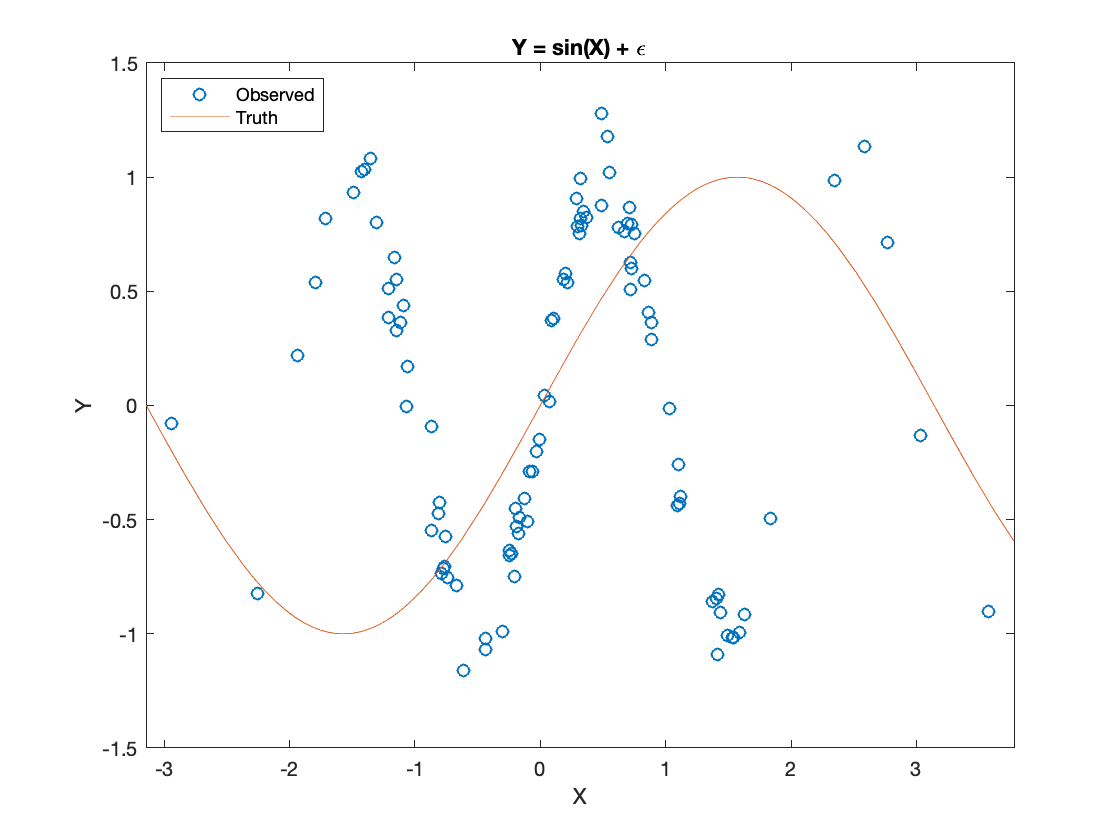

domain = [X(1)-.2 X(end)+.2];
epsilon = normrnd(0,1/9,n,k);
Y = sin(pi*X)+epsilon;
range = [-1.2 1.2];

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
title('Y = sin(X) + \epsilon');
legend('Observed', 'Truth','Location','Northwest');
xlabel('X');
ylabel('Y');
xlim(domain);
hold off;

## OLS


$$m = X(X'X)^{-1}X'Y$$


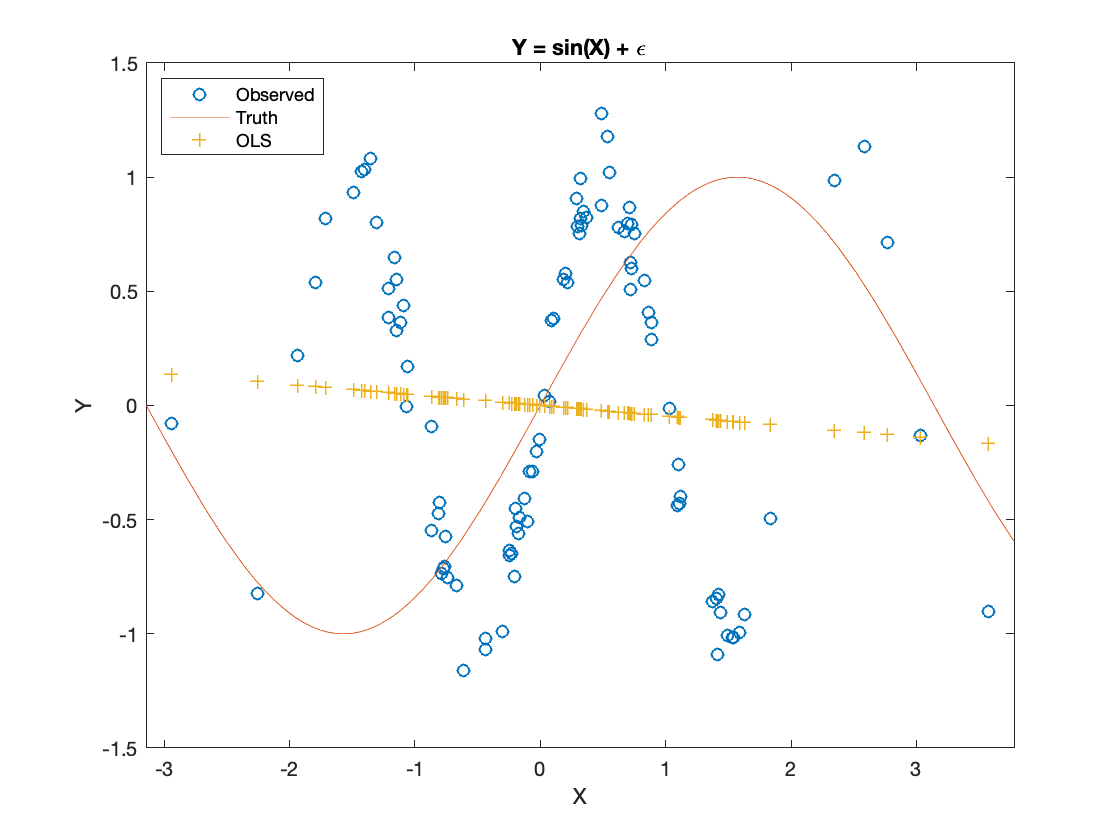

ols = X*(X'*X)^-1*X';
Y_hat = ols*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_hat,'+');
legend('Observed', 'Truth', 'OLS','Location','Northwest');
title('Y = sin(X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim(domain);
hold off;


cond_OLS = norm(ols)*norm(ols^-1)

cond_OLS = 1.1971e+22

## Nadaraya-Watson


$$\hat{m}(x_0) = \frac{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)y_l}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_0}{h}\Big)}$$
 

$\hat{Y}_{NW} = KY$, with elements $k_{i,j} = \frac{k\Big(\frac{x_j-x_i}{h}\Big)}{\sum\limits_{l=1}^{n}k\Big(\frac{x_l-x_i}{h}\Big)}$ 

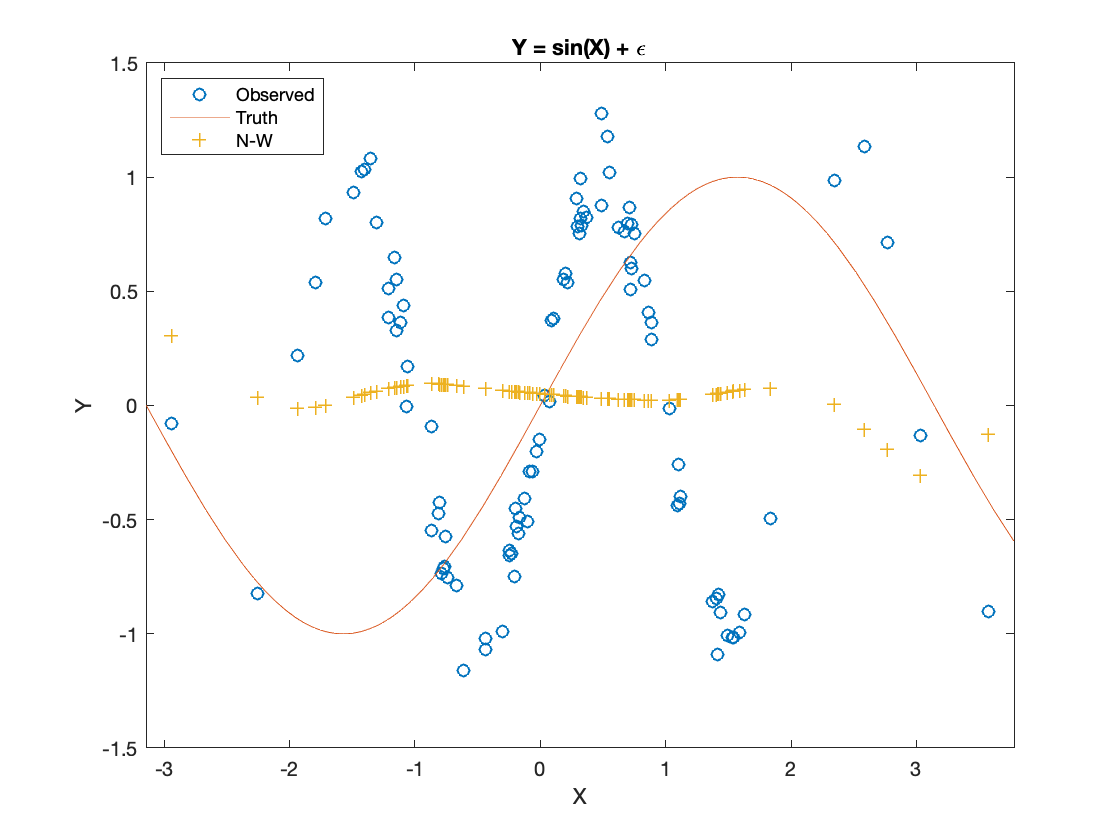

h_NW = 2.34;

% diff_ij = (x_j-x_i)/h
diff = (repmat(X',n,k)-repmat(X,k,n))/h_NW;
%Epanechnikov kernel
numerator = 3/4*(ones(n*k)-diff.^2).*(abs(diff)<=1);
denominator = repmat(sum(numerator,2),k,n);
K = numerator./denominator;

Y_NW = K*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_NW,'+');
legend('Observed', 'Truth', 'N-W','Location','Northwest');
title('Y = sin(X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim(domain);
hold off;


cond_NW = norm(K)*norm(K^-1)

cond_NW = 3.5160e+19

## Local Linear

$\tilde{m}(x_0) = [\mathbf{1_n} \enspace X_0]\big([\mathbf{1_n} \enspace X_0]'W_0[\mathbf{1_n} \enspace X_0]\big)^{-1}[\mathbf{1_n} \enspace X_0]'W_0Y$, where $X_0 = [X-x_0\mathbf{1_n} ]$ and $W_0 = diag[k\Big(\frac{x_1-x_0}{h}\Big), ... ,k\Big(\frac{x_n-x_0}{h}\Big)]$ 

$\hat{Y}_{LL} = LY$, with row i given as the i'th row of $[\mathbf{1_n} \enspace X_i]\big([\mathbf{1_n} \enspace X_i]'W_i[\mathbf{1_n} \enspace X_i]\big)^{-1}[\mathbf{1_n} \enspace X_i]'W_i$

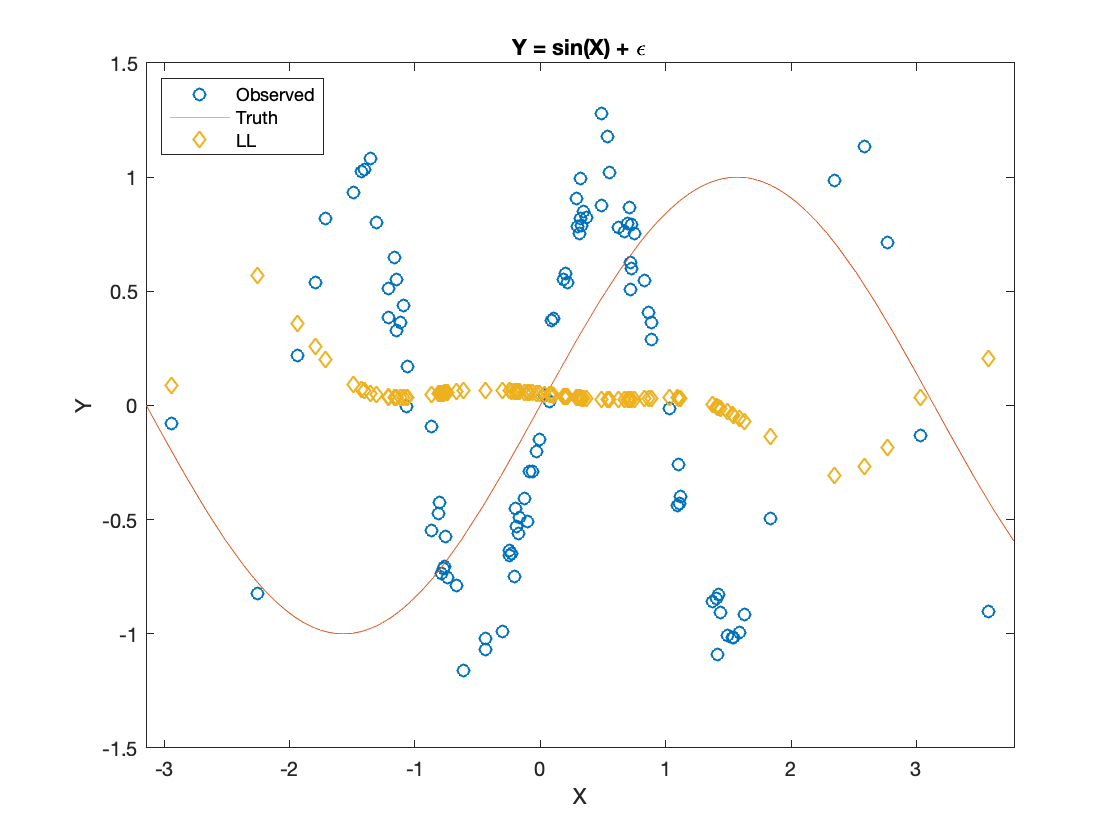

h_LL = 2.34;
L = zeros(n,n);

% diff_ij = (x_j-x_i)
diff = (repmat(X',n,k)-repmat(X,k,n));
%Epanechnikov kernel
kernel = 3/4*(ones(n*k)-(diff/h_LL).^2).*(abs(diff./h_LL)<=1);
nOnes = ones(n,1);
for i=1:n
    x = [nOnes diff(i,:)']; 
    w = diag(kernel(i,:));
    proj = x*(x'*w*x)^-1*x'*w;
    L(i,:)=proj(i,:);
end

Y_LL = L*Y;

plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x));
plot(X,Y_LL,'d');
legend('Observed', 'Truth', 'LL','Location','Northwest');
title('Y = sin(X) + \epsilon');
xlabel('X');
ylabel('Y');
xlim(domain);
hold off;

cond_LL = norm(L)*norm(L^-1)

cond_LL = 4.3749e+18

## Interpolating Cubic Natural Spline

Using Atkinson, p 168: $M_i=s''(x_i) \enspace \text{ for }i=1,2,...,n \text{ and } h_i = x_{i+1}-x_i$

$s''(x) = \frac{(x_{i+1}-x)M_i +(x-x_i)M_{i+1}}{h_i}, x_i \le x \le x_{i+1} \enspace 1\le i \le n-1$ and therefore


$$s(x) =  \frac{(x_{i+1}-x)^3M_i +(x-x_i)^3M_{i+1}}{6h_i}+\frac{(x_{i+1}-x)y_i+(x-x_i)y_{i+1}}{h_i} -\frac{h_i}{6}\big((x_{i+1}-x)M_i +(x-x_i)M_{i+1}\big)$$



$$\frac{h_{i-1}}{6}M_{i-1} + \frac{h_{i-1}+h_i}{3}M_i + \frac{h_i}{6}M_{i+1} = \frac{y_{i+1}-y_i}{h_i}-\frac{y_i-y_{i-1}}{h_{i-1}} \text{ for } i=2,3,...,n-1$$


Natural Spline: $s''(x_1)=0 \text{ and } s''(x_n)=0 \rightarrow M_1=0 \text{ and } M_n=0$


$$\frac{h_1+h_2}{3}M_2+\frac{h_2}{6}M_3 = \frac{y_3-y_2}{h_2} - \frac{y_2-y_1}{h_1} 
\text{ and } 
\frac{h_{n-2}}{6}M_{n-2} + \frac{h_{n-2}+h_{n-1}}{3}M_{n-1} = \frac{y_{n}-y_{n-1}}{h_{n-1}}-\frac{y_{n-1}-y_{n-2}}{h_{n-2}} $$


C =  [zeros(n-1,1) eye(n-1)]- [eye(n-1) zeros(n-1,1)];
h = C*X;
h_inv =h.^-1;
D = [zeros(n-2,1) eye(n-2)]+ [eye(n-2) zeros(n-2,1)];
E = diag(h(2:end-1)/6,-1)+ diag(D*h/3)+ diag(h(2:end-1)/6,1);

F = [zeros(n-2,2) diag(h_inv(2:end))]+ [diag(h_inv(1:end-1)) zeros(n-2,2)] ...
    - [zeros(n-2,1) diag(h_inv(1:end-1)) zeros(n-2,1)] ...
    - [zeros(n-2,1) diag(h_inv(2:end)) zeros(n-2,1)] ;

M = [0;(E^-1)*F*Y;0];

need all x as terms of (x-x_i)^p


$$(x_{i+1}-x)^3= \Big( (x_{i+1}-x_i)-(x-x_i)\Big)^3 = -(x-x_i)^3 +3h_i(x-x_i)^2 -3h_i^2(x-x_i) +h_i^3$$



$$s(x)= (x-x_i)^3\Big(\frac{M_{i+1}-M_i}{6h_i} \Big) +

(x-x_i)^2\Big( \frac{M_i}{2}\Big)+

(x-x_i)\Big( \frac{y_{i+1}-y_i}{h_i}-\frac{h_i}{6}(2M_i+M_{i+1})\Big)+

y_i
$$


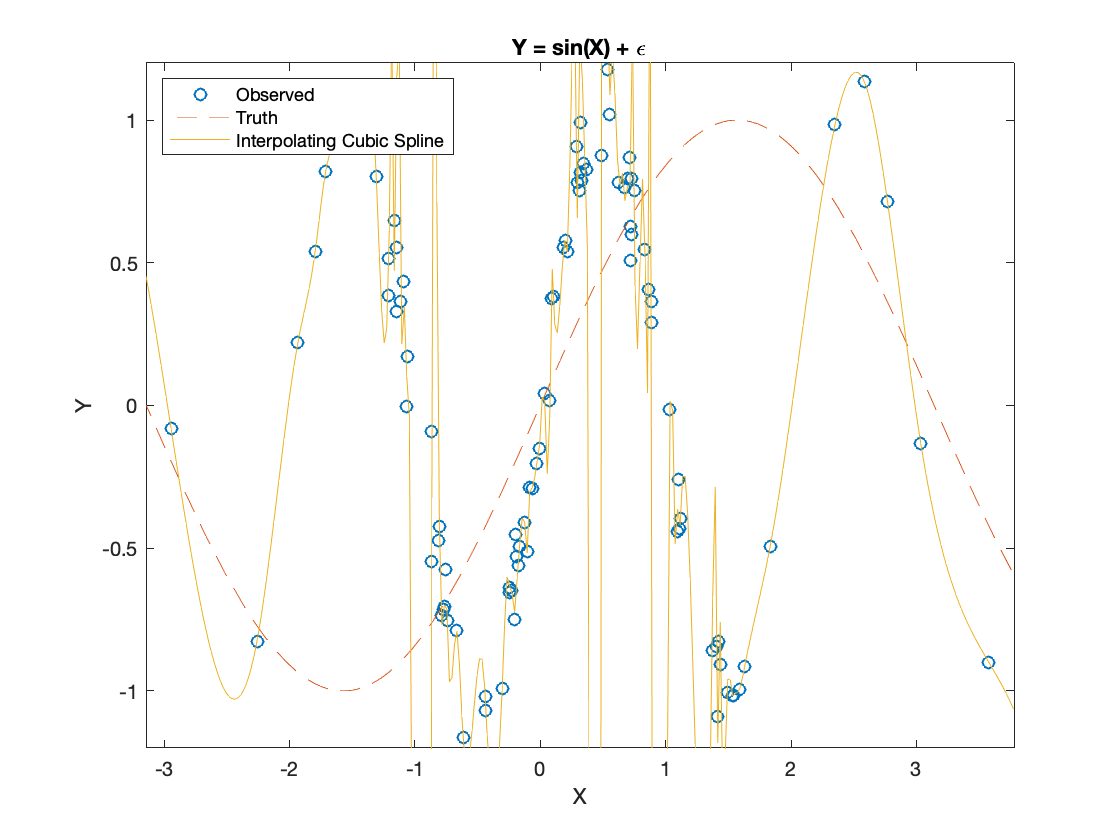

%coefs(i,1)*(X-breaks(i))^(k-1) + coefs(i,2)*(X-breaks(i))^(k-2) + ... + coefs(i,k-1)*(X-breaks(i)) + coefs(i,k).

coefs = zeros(n-1,4);

coefs(:,1) = diag(h_inv)*C*M/6;
coefs(:,2) = M(1:end-1)/2;
C_1 = [zeros(n-1,1) eye(n-1)]+2*[eye(n-1) zeros(n-1,1)];
coefs(:,3) = diag(h_inv)*C*Y-diag(h)*C_1*M/6;
coefs(:,4) = Y(1:end-1);
breaks = X;
pp = mkpp(breaks,coefs);

%nat = csape(X,Y,'variational');

xx = domain(1):0.02:domain(2);
plot(X,Y,'o');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,ppval(pp,xx),'-')
%plot(xx,csapi(X,Y,xx),':')
%plot(xx,ppval(nat,xx),'-.')
title('Y = sin(X) + \epsilon');
legend('Observed', 'Truth','Interpolating Cubic Spline','Location','Northwest');
xlabel('X');
ylabel('Y');
xlim(domain);
ylim(range);
hold off;

## Regression Cubic B-Spline

on bsplines from Atkinson, p 174 "often leads to numerical schemes that are ill-conditioned."

k = 9; %internal

step = floor(n/(k+1));
indecies = [1 1+step:step:n-1 n];

knots = X(indecies);

for i=1:k+1
    X(indecies(i):indecies(i+1))
end

ans =    -2.9443
   -2.2588
   -1.9330
   -1.7947
   -1.7115
   -1.4916
   -1.4224
   -1.4023
   -1.3499
   -1.3077


ans =    -1.2141
   -1.2075
   -1.1658
   -1.1480
   -1.1471
   -1.1135
   -1.0891
   -1.0689
   -1.0616
   -0.8649


ans =    -0.8637
   -0.8095
   -0.8045
   -0.7873
   -0.7697
   -0.7648
   -0.7549
   -0.7423
   -0.6669
   -0.6156


ans =    -0.4390
   -0.4336
   -0.3034
   -0.2437
   -0.2414
   -0.2256
   -0.2050
   -0.1961
   -0.1924
   -0.1774


ans =    -0.1649
   -0.1241
   -0.1022
   -0.0825
   -0.0631
   -0.0301
   -0.0068
    0.0326
    0.0774
    0.0859


ans =     0.1049
    0.1873
    0.1978
    0.2157
    0.2916
    0.2939
    0.3129
    0.3188
    0.3192
    0.3252


ans =     0.3426
    0.3714
    0.4882
    0.4889
    0.5377
    0.5525
    0.6277
    0.6715
    0.6966
    0.7147


ans =     0.7172
    0.7223
    0.7254
    0.7269
    0.7481
    0.8351
    0.8622
    0.8884
    0.8886
    1.0347


ans =     1.0933
    1.1006
    1.1093
    1.1174
    1.3703
    1.4090
    1.4172
    1.4193
    1.4384
    1.4897


ans =     1.5326
    1.5442
    1.5877
    1.6302
    1.8339
    2.3505
    2.5855
    2.7694
    3.0349
    3.5784



% 
% p3 = bSpline(X,3);
% p4 = bSpline(X,4);
% p5 = bSpline(X,5);
% p6 = bSpline(X,6);
% p7 = bSpline(X,7);
% p8 = bSpline(X,8);
% 
% G = [ppval(p3,X) ppval(p4,X) ppval(p5,X) ppval(p6,X) ...
%     ppval(p7,X) ppval(p8,X)];
% 
% RS = G*(G'*G)^-1*G';
% Y_RS = RS*Y;
% 
% beta = (G'*G)^-1*G'*Y;
% 
% coefs = p3.coefs*beta(1) + p4.coefs*beta(2) + ...
%     p5.coefs*beta(3) + p6.coefs*beta(4) + ...
%     p7.coefs*beta(5) + p8.coefs*beta(6);
% 
% breaks = X;
% pp = mkpp(breaks,coefs);
% 
% xx = domain(1):0.02:domain(2);
% plot(X,Y,'o',X,Y_RS,'d');
% hold on;
% fplot(@(x) sin(pi*x),'--');
% plot(xx,ppval(pp,xx),'-')
% title('Y = sin(X) + \epsilon');
% legend('Observed','Estimated', 'Truth','B-Spline Reg','Location','Northwest');
% xlabel('X');
% ylabel('Y');
% xlim(domain);
% ylim(range);
% hold off;
% 
% cond_RS = norm(RS(2:end-1,2:end-1))*norm(RS(2:end-1,2:end-1)^-1)

## Smoothing Cubic B-Spline

beta that minimizes the following


$$||y-G\beta||_2^2 + \lambda\beta^T\Omega\beta \text{, where } G_{ij} = g_j(x_i) \text{ and } \Omega_{ij} = \int g''_i(t)g''_j(t)dt \enspace i,j = 1,...,n$$



$$\hat{\beta} = (G^TG+\lambda\Omega)^{-1}G^Ty$$


lambda = 1;
pp = repmat(mkpp(zeros(n,1),zeros(n-1,4)),n-4,2);

for i=1:n-4
    pp(i,1) = bSpline(X,i+2);
    pp(i,2) = fnder(fnder(pp(i,1)));
end

G = [ppval(p3,X) ppval(p4,X) ppval(p5,X) ppval(p6,X) ...
    ppval(p7,X) ppval(p8,X)];

omega = zeros(n-4,n-4);

for i=1:n-4
    for j=1:n-4
        coefs = zeros(n-1,3);
        coefs(:,1) = pp(i,2).coefs(:,1).*pp(j,2).coefs(:,1);
        coefs(:,2) = pp(i,2).coefs(:,2).*pp(j,2).coefs(:,1) + ...
            pp(i,2).coefs(:,1).*pp(j,2).coefs(:,2);
        coefs(:,3) = pp(i,2).coefs(:,2).*pp(j,2).coefs(:,2);
        integral = fnint(mkpp(X,coefs));
        omega(i,j) = sum(ppval(integral,X));
    end
end

inner = (G'*G+lambda*omega)^-1*G';

Matrix dimensions must agree.

S = G*inner;
Y_S = S*Y;

beta = inner*Y;


coefs = p3.coefs*beta(1) + p4.coefs*beta(2) + ...
    p5.coefs*beta(3) + p6.coefs*beta(4) + ...
    p7.coefs*beta(5) + p8.coefs*beta(6);

breaks = X;
pp = mkpp(breaks,coefs);

xx = domain(1):0.02:domain(2);
plot(X,Y,'o',X,Y_S,'d');
hold on;
fplot(@(x) sin(pi*x),'--');
plot(xx,ppval(pp,xx),'-')
title('Y = sin(X) + \epsilon');
legend('Observed','Estimated', 'Truth','Smoothed B-Spline','Location','Northwest');
xlabel('X');
ylabel('Y');
xlim(domain);
%ylim(range);
hold off;

cond_S = norm(S(2:end-1,2:end-1))*norm(S(2:end-1,2:end-1)^-1)


## Matlab algorithms


scs = csaps(X,Y);
fnplt(scs), hold on, plot(X,Y,'o')
legend('smoothing spline','noisy data'), hold off


[scs,p] = csaps(X,Y); 
p
fnplt(scs), hold on
fnplt(csaps(X,Y,p/2),'--')
fnplt(csaps(X,Y,(1+p)/2),':'), plot(X,Y,'o')
legend('smoothing spline','more smoothed','less smoothed',...
    'noisy data'), hold off

2 things need to take into account:

condition number very dependent on h and number of knots

also perhaps on functions use to calculate functions for estimator

B-spline: knots and some other parameter

series estimator

choice of h, knots, etc

non-stochastic choice of h,k (not data dependent) tensor product-ish

and/or

stochastic choices, (data driven)

mapping from book: 

- parmutter and mccloud: trace of orthogonal projector of residual M_x = I-P_x <----!!!!

- need theory that relates condition number to smoothness imparting on estimation of regressors

add additional measure of smoothness

leverage in linear models 

Thursday: Vanya

Research topic: spanish and portuguese, FR, BR, PO (grant)

post 1822 - present brazilian literature

catalogue of portuguese characters in brazilian literature, 

searchable database, 

Tania Martushelly

measures of sympathy, etc

Us vs Them (portuguese)

## Specification help

Nadaraya-Watson: [https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf](https://www.ssc.wisc.edu/~bhansen/718/NonParametrics1.pdf) and [http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf](http://www.maths.manchester.ac.uk/~peterf/MATH38011/NPR%20N-W%20Estimator.pdf) (cause I can't put my hands on the notes from Fall 2017)

Local linear: [http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf](http://courses.ieor.berkeley.edu/ieor265/lecture_notes/ieor265_lec6.pdf)

Splines: [http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf](http://www.stat.cmu.edu/~larry/=sml/nonpar.pdf) and [http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf](http://cda.psych.uiuc.edu/matlab_pdf/splines.pdf)

## Functions

function pp = bSpline(x,center)
% makes a cubic B-spline from x(center-2) to x(center+2)
% with breaks over all x (will do knots later)
n = length(x);
if center>n-2 | center<3
    error('Must have at least 5 points for cubic B-spline')
end
temp = bspline(x(center-2:center+2));
leadZeros = center-3;
trailZeros = n-center-2;

coefs = [zeros(leadZeros,4); temp.coefs; zeros(trailZeros,4)];
pp = mkpp(x,coefs);
end